**Traitement des données**

Importation des données

clear all;

dailycrypto = readtable("C:\Users\jeanb\Documents\M2_272\TOBAM\daily_crypto_data.csv");

Mktcapvol = readtable("C:\Users\jeanb\Documents\M2_272\TOBAM\market_caps_daily.csv");

volumebinance = readtable("C:\Users\jeanb\Documents\M2_272\TOBAM\volume_binance_daily.csv");

Mktcapvoldata=table2array(Mktcapvol(:,2:end));
volumebinancedata=table2array(volumebinance(:,2:end));
dailycryptodata=table2array(dailycrypto(:,2:end));

Récupération des rendements en continue des daily cryptos 

nbcol=size(dailycrypto,2);
rdtdaily=diff(log(dailycryptodata));
% récupération du nom des colonnes 
nomsColonnesString = 'bitcoin,ethereum,bitcoin-cash,ripple,litecoin,tron,ethereum-classic,chainlink,stellar,cardano,dash,tezos,binancecoin,solana,matic-network,dogecoin,avalanche-2';
% Diviser la chaîne en cellules
cellulesNomsColonnes = strsplit(nomsColonnesString, ',');
% Convertir les cellules en une liste
nomsColonnes = cellstr(cellulesNomsColonnes);

Représentation de la distribution des rendements 

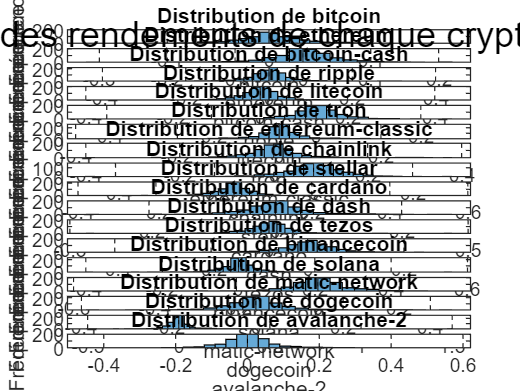

% Créer une nouvelle figure
figure;
% Nombre total de colonnes
nbColonnes = size(rdtdaily, 2);
% Boucle pour créer les subplots
for i = 1:nbColonnes
    subplot(nbColonnes, 1, i);
    
    % Afficher l'histogramme de la colonne actuelle
    histogram(rdtdaily(:, i));
    
    % Ajouter des étiquettes et un titre
    xlabel(nomsColonnes{i});
    ylabel('Fréquence');
    title(['Distribution de ' nomsColonnes{i}]);
end

% Ajuster la disposition
sgtitle('Distribution des rendements de chaque cryptomonnaies ');

Test de normalité des rendements

Kurtosisrdt=kurtosis(rdtdaily);Skewnessrdt=skewness(rdtdaily);

A première vue, nous pouvons voir que toutes les Kurtosis des rendements de chaque cryptomonnaies sont largement supérieur à 3, laissant penser que les rendements ne suivent pas une loi normale. Nous allors vérifier celà à l'aide du test de Jarque Bera,

h=zeros(nbColonnes,1);p=zeros(nbColonnes,1);jbstat=zeros(nbColonnes,1);critval=zeros(nbColonnes,1);
for i=1:nbColonnes
    [h(i,1),p(i,1),jbstat(i,1),critval(i,1)] = jbtest(rdtdaily(:,i),0.01);
end

En faisant, le test de Jarque Bera nous rejetons la normalité des rendements pour toutes les cryptomonnaies à un seuil de 1%

Matrice des corrélations 

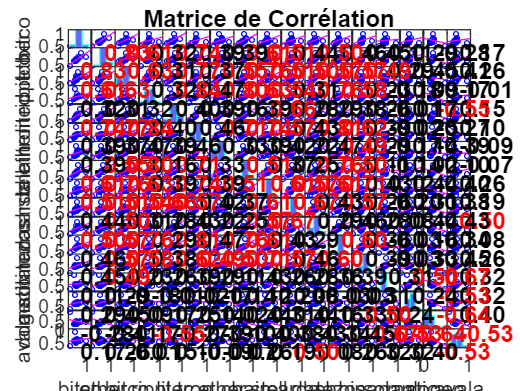

matriceCorrelation = corr(rdtdaily);
Covariance = cov(rdtdaily);
% Ajustement de la taille de la figure
figure('Position', [100, 100, 800, 600]); % [left, bottom, width, height]
corrplot(matriceCorrelation, 'varNames', nomsColonnes, 'testR', 'on');
% Ajouter un titre
title('Matrice de Corrélation');

Etude des autocorrélations partielles des rendements

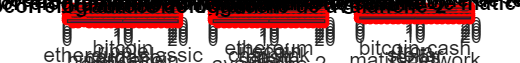

% Créer une nouvelle figure
figure('Position', [100, 100, 5000, 600]);
% Boucle pour créer les subplots
for i = 1:nbColonnes
    subplot(nbColonnes, 3, i);
    
    % Afficher l'histogramme de la colonne actuelle
    parcorr(rdtdaily(:, i));
    
    % Ajouter des étiquettes et un titre
    xlabel(nomsColonnes{i});
    ylabel('erreur');
    title(['autocorrélogramme de ' nomsColonnes{i}]);
end

**Les choix diversification **

Dispersion des monnaies par ecart types et moyennes de leur capitalisation, de leur rendement et de leur volume

meanCap=mean(Mktcapvoldata);stdCap=std(Mktcapvoldata);
meanrdt=mean(rdtdaily);stdrdt=std(rdtdaily);
meanVolume=mean(volumebinancedata);stdVolume=std(volumebinancedata);

*Diversfication par la capitalisation*

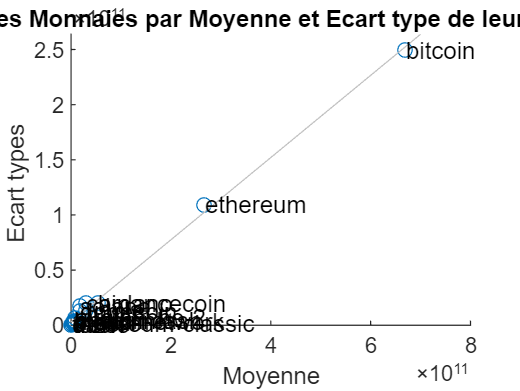

% Tracer un graphe de dispersion
figure('Position', [100, 100, 800, 600]);
scatter(meanCap, stdCap);
hold on;

% Tracer la droite de régression linéaire
lsline;

% Ajouter des étiquettes aux points
for i = 1:length(nomsColonnes)
    text(meanCap(i), stdCap(i), nomsColonnes{i});
end

% Ajouter des étiquettes et un titre
xlabel('Moyenne');
ylabel('Ecart types ');
title('Dispersion des Monnaies par Moyenne et Ecart type de leur capitalisation ');

Nous retraçons la droite de régression en supprimant Bitcoin et Ethereum puisque leur capitalisation est largement plus élevée que les autres cryptomonnaies. Ainsi, nous allons les mettre dans une catégorie LargeCap Crypto.

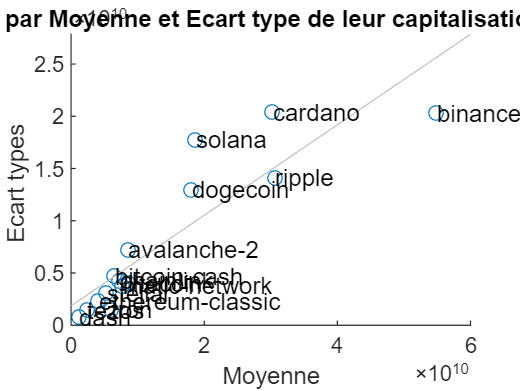

% Tracer un graphe de dispersion
figure('Position', [100, 100, 800, 600]);
scatter(meanCap(3:end), stdCap(3:end));
hold on;

% Tracer la droite de régression linéaire
lsline;

% Ajouter des étiquettes aux points
for i = 3:length(nomsColonnes)
    text(meanCap(i), stdCap(i), nomsColonnes{i});
end

% Ajouter des étiquettes et un titre
xlabel('Moyenne');
ylabel('Ecart types ');
title('Dispersion des Monnaies par Moyenne et Ecart type de leur capitalisation sans bitcoin et ethereum');

Au vue de ce graphique nous pouvons mieux discerner les autres capitalisations avec en MidCap (Cardano, BinanceCoin, ripple, solana, Dogecoin, Avanlache-2) et en SmallCap (Bitcoin-cash, chainlink, litecoin, matic-network, stellar,ethereum-classic, tron, tezos, dash)

* Diversification par le volume *

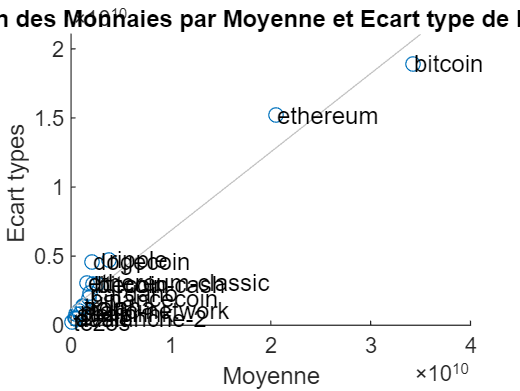

% Tracer un graphe de dispersion
figure('Position', [100, 100, 800, 600]);
scatter(meanVolume, stdVolume);
hold on;

% Tracer la droite de régression linéaire
lsline;

% Ajouter des étiquettes aux points
for i = 1:length(nomsColonnes)
    text(meanVolume(i), stdVolume(i), nomsColonnes{i});
end

% Ajouter des étiquettes et un titre
xlabel('Moyenne');
ylabel('Ecart types ');
title('Dispersion des Monnaies par Moyenne et Ecart type de leur volume ');

Des résultats similaires à celui de la régression sur le volume, les plus gros volumes d'échanges sont les plus grosses capitalisations .

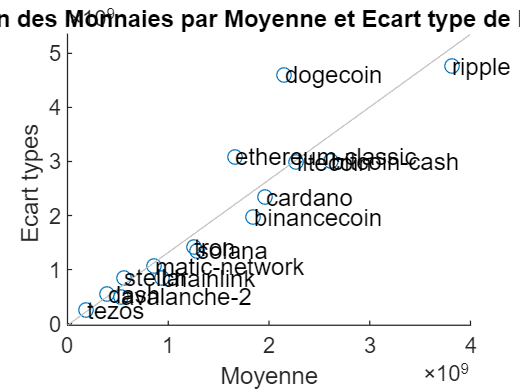

% Tracer un graphe de dispersion
figure('Position', [100, 100, 800, 600]);
scatter(meanVolume(3:end), stdVolume(3:end));
hold on;

% Tracer la droite de régression linéaire
lsline;

% Ajouter des étiquettes aux points
for i = 3:length(nomsColonnes)
    text(meanVolume(i), stdVolume(i), nomsColonnes{i});
end

% Ajouter des étiquettes et un titre
xlabel('Moyenne');
ylabel('Ecart types ');
title('Dispersion des Monnaies par Moyenne et Ecart type de leur volume');

Néanmoins nous avons quelques différences entre les volumes Mid et les Mid cap; les "small" Volumes et les "small" capitalisations. 

MidVolume=dogecoin,ripple, ethereum-classic,litecoin, bitcoin-cash, cardano, binancecoiin 

SmallVolume=Tron, solana, matic-network, stellar, chainlink, dash, avalanche-2,tezos 

Le smallVolume est un facteur essentiel à prendre au sein de la construction de notre portefeuille puisqu'il indique une faible liquidité du produit donc la difficulté de rebalancer le portefeuille si nécessaire.

*Diversification par les rendements*

Nous allons regarder la dispersion des cryptos en fonction de leur moyenne et de leur écart type, ces résultats pourront être vu comme un proxy du ratio de Sharpe (en supposant un taux sans risque à 0).

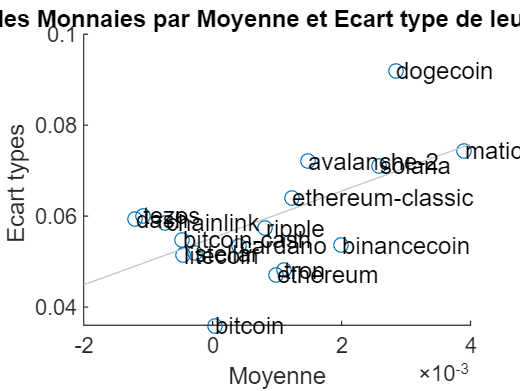

% Tracer un graphe de dispersion
figure('Position', [100, 100, 800, 600]);
scatter(meanrdt, stdrdt);
hold on;

% Tracer la droite de régression linéaire
lsline;

% Ajouter des étiquettes aux points
for i = 1:length(nomsColonnes)
    text(meanrdt(i), stdrdt(i), nomsColonnes{i});
end

% Ajouter des étiquettes et un titre
xlabel('Moyenne');
ylabel('Ecart types ');
title('Dispersion des Monnaies par Moyenne et Ecart type de leurs rendements ');

Nous constatons qu'une partie des rendements rapportent des rendements négatifs avec un minimum de volatilité.

**Most diverisified portfolio (MDP)**

Dans un premier temps, nous allons considérer le MDP, le portefeuille répartit en fonction des capitalisations catégoriser juste au-dessus (LargeCap, MidCap et SmallCap)

Concernant le taux sans risque nous allons prendre 

La formule pour la matrice de covariance shrinkée (*C*shrunk��) selon DGU est donnée par :

*C*shrunk�=*δ*⋅*C*+(1−*δ*)⋅*v*ˉ⋅**1***T*

où *δ* est un paramètre de régularisation entre 0 et 1, *v*ˉ est la moyenne des variances de chaque actif, **1** est un vecteur de 1 et *T* représente la transposition.

%initialisation des poids 

%weight=ones(size(rdtdaily,2), 1) / length(rdtdaily);
% calcul du concentration ratio et calcul du  volatility-weighted average
% correlation à l'aide des fonctions CR et VMAC
%Nous allons d'abord Shrinker nos covariances afin d'éviter des valeurs qui
%explosent lorsque nous inversons la matrice lorsque les variances et
%covairances sont inférieures à 0

% Paramètre de régularisation (à ajuster)
delta = 0.05;

% Calcul de la matrice de covariance shrinkée selon DGU
v = var(rdtdaily); % Returns est une matrice contenant les rendements historiques
bar_v = mean(v);
C_shrunk = delta * Covariance + (1 - delta)*diag(Covariance) .* ones(nbColonnes, nbColonnes);
% Fonction objective
DR=@(w) sqrt(VMAC(w,C_shrunk)*(1-CR(w,C_shrunk))+CR(w,C_shrunk));
% Contraintes d'égalité
Aeq = ones(1, size(rdtdaily,2));  % Somme des parts égale à 1
beq = 1;
% Contrainte non linéaire
nonlincon = @(w) FirstOrderCond(w, C_shrunk);
% Bornes des variables de décision
lb = zeros(size(rdtdaily,2), 1);  % Parts non négatives
ub = ones(size(rdtdaily,2), 1);   % Parts inférieures ou égales à 1


% Initialisation des variables
x0 = ones(size(rdtdaily,2), 1) / length(rdtdaily);
% Options pour la fonction d'optimisation
options = optimoptions('fmincon', 'Algorithm', 'interior-point', 'Display', 'iter');

% Résolution du problème d'optimisation
[xMDP,fvalMDP,exitflagMDP,outputMDP,lambdaMDP,gradMDP,hessianMDP]= fmincon(DR, x0, [], [], Aeq, beq, lb, ub, nonlincon, options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      18    1.670278e-02    9.813e-01    1.000e-01
    1      36    5.834946e-02    9.329e-01    7.283e-01    3.702e-02
    2      54    7.092312e-02    2.818e-01    5.361e-02    4.762e-01
    3      72    7.913683e-02    2.584e-01    7.790e-02    1.244e-01
    4      91    7.913901e-02    2.584e-01    7.790e-02    6.960e-04
    5     109    7.922620e-02    2.582e-01    7.813e-02    1.983e-02
    6     127    7.922494e-02    2.582e-01    7.814e-02    4.894e-04
    7     145    8.150461e-02    2.902e-01    4.232e-02    1.529e-02
    8     163    8.252321e-02    3.100e-01    3.111e-02    1.758e-02
    9     181    8.299951e-02    3.207e-01    2.028e-02    1.139e-02
   10     199    8.333544e-02    3.280e-01    1.146e-02    7.670e-03
   11     217    8.360751e-02    3.337e-01    4.942e-03    5.643e-03
   12     235    8.384757e-02    3.383e-01    1

DRMDP=sqrt(VMAC(xMDP,C_shrunk)*(1-CR(xMDP,C_shrunk))+CR(xMDP,C_shrunk));
% Affichage des résultats
disp('Résultats de l''optimisation :');

Résultats de l'optimisation :


disp(['Variables optimales : ']);xMDP

Variables optimales : 


xMDP =     0.0228
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


disp(['Variance du portefeuille MDP : ', num2str(xMDP'* C_shrunk * xMDP)]);

Variance du portefeuille MDP : 0.003265


disp(outputMDP);

         iterations: 166
          funcCount: 3007
    constrviolation: 0.3692
           stepsize: 7.5835e-06
          algorithm: 'interior-point'
      firstorderopt: 0.0705
       cgiterations: 161
            message: '↵Solver stopped prematurely.↵↵fmincon stopped because it exceeded the function evaluation limit,↵options.MaxFunctionEvaluations = 3.000000e+03.↵↵'
       bestfeasible: []




%Récupération du rendement du portefeuille avec la pondération du
%portefeuille
RptfMDP=xMDP'*rdtdaily';
MktcapvolMDP=xMDP'*Mktcapvoldata';
volumeMDP=xMDP'*volumebinancedata';

 **Equal-risk-contribution portfolio ERC**

Un portefeuille à contribution égale au risque (ERC) consiste à déterminer les poids des actifs de manière à ce que chaque actif contribue de manière égale à la volatilité totale du portefeuille.

% Nombre d'actifs
numAssets = size(C_shrunk, 1);
% Initialisation des poids égaux
weights = ones(numAssets, 1) / numAssets;

% Fonction objective pour minimiser la contribution au risque
objective = @(w) sum(w .* (C_shrunk * w));

% Contraintes
Aeq = ones(1, numAssets);  % Somme des pondérations égale à 1
beq = 1;

% Bornes des variables de décision (pondérations)
lb = zeros(numAssets, 1);  % Pondérations non négatives
ub = ones(numAssets, 1);   % Pondérations inférieures ou égales à 1

% Options pour la fonction d'optimisation
options = optimoptions('fmincon', 'Display', 'iter');

% Résolution du problème d'optimisation
xERC = fmincon(objective, weights, [], [], Aeq, beq, lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      18    3.589519e-03    0.000e+00    2.317e-03
    1      36    3.588142e-03    2.220e-16    1.257e-03    2.141e-04
    2      54    3.509306e-03    2.220e-16    1.074e-03    1.227e-02
    3      72    3.072350e-03    1.110e-16    1.330e-03    6.822e-02
    4      90    3.014185e-03    1.110e-16    1.400e-03    1.006e-02
    5     108    2.864062e-03    2.220e-16    1.659e-03    3.591e-02
    6     126    2.735069e-03    0.000e+00    1.831e-03    2.992e-02
    7     144    2.727026e-03    2.220e-16    1.839e-03    6.169e-03
    8     163    2.694906e-03    0.000e+00    1.871e-03    8.676e-03
    9     182    2.666050e-03    0.000e+00    1.476e-03    8.722e-03
   10     201    2.641176e-03    0.000e+00    1.299e-03    9.580e-03
   11     219    2.533019e-03    1.110e-16    1.407e-03    4.539e-02
   12     238    2.512070e-03    1.110e-16    1


% Affichage des résultats
disp('Pondérations pour un portefeuille à contribution égale au risque :');

Pondérations pour un portefeuille à contribution égale au risque :


disp(xERC');

  Columns 1 through 12

    0.9998    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 13 through 17

    0.0000    0.0000    0.0000    0.0000    0.0000




% Calcul de la variance du portefeuille
portfolioVolatilityERC = xERC' * C_shrunk * xERC;

% Affichage de la variance du portefeuille
disp(['Variance du portefeuille ERC : ', num2str(portfolioVolatilityERC)]);

Variance du portefeuille ERC : 0.0012963



% Calcul du diversification Ratio
DRERC=sqrt(VMAC(xERC,C_shrunk)*(1-CR(xERC,C_shrunk))+CR(xERC,C_shrunk));
%Récupération du rendement du portefeuille avec la pondération du
%portefeuille
RptfERC=xERC'*rdtdaily';
MktcapvolERC=xERC'*Mktcapvoldata';
volumeERC=xERC'*volumebinancedata';

**Equal-weighted portfolio EW**

Calcul dur Dispersion Ratio, pour un portefeuille équipondéré, 

xEW=ones(numAssets, 1) / numAssets;
DREW=sqrt(VMAC(xEW,C_shrunk)*(1-CR(xEW,C_shrunk))+CR(xEW,C_shrunk));
% Calcul de la variance du portefeuille EW
portfolioVolatilityEW = xEW' * C_shrunk * xEW;
disp(['Variance du portefeuille EW: ', num2str(portfolioVolatilityEW)]);

Variance du portefeuille EW: 0.0035895


%Récupération du rendement du portefeuille avec la pondération du
%portefeuille
RptfEW=xEW'*rdtdaily';
MktcapvolEW=xEW'*Mktcapvoldata';
volumeEW=xEW'*volumebinancedata';

**Minimum-variance portfolio**

% Fonction objective pour minimiser la variance
objective = @(x) x' * C_shrunk * x;

% Contraintes linéaires
Aeq = ones(1, size(rdtdaily,2));  % Somme des parts égale à 1
beq = 1;

% Bornes des variables de décision (parts dans le portefeuille)
lb = zeros(size(rdtdaily,2), 1);  % Parts non négatives
ub = ones(size(rdtdaily,2), 1);   % Parts inférieures ou égales à 1

% Initialisation des parts
x0 = ones(size(rdtdaily,2), 1) / length(rdtdaily);

% Options pour la fonction d'optimisation
options = optimoptions('quadprog', 'Display', 'iter');
% Résolution du problème d'optimisation
[xMinVar,fvalMinVar,exitflagMinVar,outputMinVar,lambdaMinVar] = quadprog(C_shrunk, [], [], [], Aeq, beq, lb, ub, x0, options);

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    5.186855e-01   1.600000e+01   9.200216e-01     1.000000e+00  
    1    1.818380e-03   8.000000e-03   4.600108e-04     5.632013e-02  
    2    1.788398e-03   1.022877e-05   5.881678e-07     2.041179e-04  
    3    6.697460e-04   2.588033e-06   1.488154e-07     7.814468e-04  
    4    6.504240e-04   7.664849e-09   4.407392e-10     2.349178e-07  
    5    6.479931e-04   0.000000e+00   5.502988e-18     3.316075e-14  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

DRMinVar=sqrt(VMAC(xMinVar,C_shrunk)*(1-CR(xMinVar,C_shrunk))+CR(xMinVar,C_shrunk));
% Affichage des résultats
disp('Résultats de l''optimisation :');

Résultats de l'optimisation :


disp(['Parts optimales : ', num2str(xMinVar')]);

Parts optimales : 1  2.1095e-13  1.7084e-12  1.7631e-12  1.7783e-12  6.8847e-13   1.932e-12  2.1598e-12  2.1643e-12  2.0494e-12  2.1503e-12   2.187e-12  1.3441e-12  1.0644e-12  1.2059e-12  5.5576e-13  1.3123e-12


disp(outputMinVar);

            message: '↵Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 5.502988e-18,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵3.316075e-14, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.↵↵'
          algorithm: 'interior-point-convex'
      firstorderopt: 3.3165e-14
    constrviolation: 0
         iterations: 5
       linearsolver: 'dense'
       cgiterations: []



% Calcul de la variance du portefeuille MinVar
portfolioVolatilityMinVar = xMinVar' * C_shrunk * xMinVar;
disp(['Variance du portefeuille MinVar : ', num2str(portfolioVolatilityMinVar)]);

Variance du portefeuille MinVar : 0.001296


%Récupération du rendement du portefeuille avec la pondération du
%portefeuille
RptfMinVar=xMinVar'*rdtdaily';
MktcapvolMinVar=xMinVar'*Mktcapvoldata';
volumeMinVar=xMinVar'*volumebinancedata';

Comparaison des DR pour savoir lequel est le plus petit et le plus grand. 

min([DRMDP,DRMinVar,DRERC,DREW]);max([DRMDP,DRMinVar,DRERC,DREW]);

Le DR le plus grand est celui du portefeuille MDP et le plus petit celui du portefeuille ERC.

**Estimation des CAPM**

Récupération du taux sans risque sur la période de la base donnée afin de modéliser la prime de risque,

% Lisez le fichier CSV en tant que matrice
donnees_matrice = readmatrix('C:\Users\jeanb\Documents\M2_272\TOBAM\^IRX.csv', 'HeaderLines', 1);

% Récupérez la colonne "Adj Close"
adj_close = donnees_matrice(:, 6);  % La sixième colonne correspond à "Adj Close"
% Supprimez les lignes contenant NaN dans la colonne "Adj Close"
adj_closeRf = adj_close(~isnan(adj_close));

% Récupération de la moyenne du taux sans risque sur l'ensemble de la
% période (rendement annualisé)
Rf=mean(adj_closeRf);


Etude des Sharpes Ratio des portefeuille

SharpeMDP=(mean(RptfMDP)-Rf/252)/sqrt(xMDP'* C_shrunk * xMDP);
SharpeERC=(mean(RptfERC)-Rf/252)/sqrt(xERC'* C_shrunk * xERC);
SharpeEW=(mean(RptfEW)-Rf/252)/sqrt(xEW'* C_shrunk * xEW);
SharpeMinVAR=(mean(RptfMinVar)-Rf/252)/sqrt(xMinVar'* C_shrunk * xMinVar);

Le meilleur Sharpe Ratio est celui du portefeuille MDP

L'excés de rendement (différence entre le rendement de la cryptomonnaie et le taux sans risque) expliqué par le volume

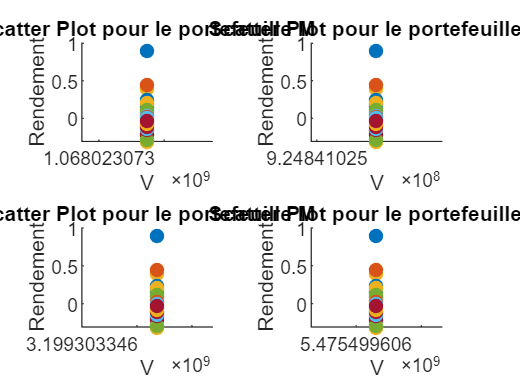

Index in position 2 exceeds array bounds. Index must not exceed 1.

T=length(rdtdaily);
CMKT=zeros(T+1,2); % On va supposer deux facteurs marchés Bitcoin et Ethereum
Rptf=[RptfMDP' RptfERC' RptfEW' RptfMinVar'];
Mktcapvolptf=[MktcapvolMDP' MktcapvolERC' MktcapvolEW' MktcapvolMinVar'];
Volumeptf=[volumeMDP' volumeERC' volumeEW' volumeMinVar'];
betaVolume=zeros(2,4);betaVol=zeros(2,4);betaMKTBitcoin=zeros(2,4);betaMKTETH=zeros(2,4);
statsVolume=zeros(4,4);statsVol=zeros(4,4);statsMKTBitcoin=zeros(4,4);statsMKTETH=zeros(4,4);
pvaluevolume=zeros(4,2);pvaluevol=zeros(4,2);pvalueMKTBitcoin=zeros(4,2);pvalueMKTETH=zeros(4,2);
nomstrategies=['MDP' 'ERC' 'EW' 'MinVar']; Facteur=['Volume' 'Volatilité' 'Bitcoin' 'ETH'];

%Boucle sur les 4 portefeuilles
for i=1:4
    % on réadapte la matrice rdt pour qu'elle soit de même taille que le
    % Volume 
    X=[ones(T+1,1) Volumeptf(:,i)];
    Y=[0;Rptf(:,i)];

    [betaVolume(:,i),~,res,~,statsVolume(i,:)] = regress(Y, X); % Exécution de la régression
    % Calcul de la statistique t pour chaque coefficient
    %Calcul de la variance des r´esidus:
    sigma2 = (res'*res)/(T-1);
    %Calcul de la variance des coefficients:
    varb = sigma2 * inv(X'*X);
    %Calcul de l%´ecart-type des coefficients:
    etype = sqrt(diag(varb));
    t_stat_volume = betaVolume(:,i)./etype; % 4 correspond à l'index de l'erreur standard
    pvaluevolume(i,:)=2*(1-normcdf(abs(t_stat_volume)));
    % Capitalisation
    X=[ones(T+1,1) Mktcapvolptf(:,i)];
    [betaVol(:,i),~,res,~,statsVol(i,:)] = regress(Y, X); % Exécution de la régression

    %Calcul de la variance des r´esidus:
    sigma2 = (res'*res)/(T-1);
    %Calcul de la variance des coefficients:
    varb = sigma2 * inv(X'*X);
    %Calcul de l%´ecart-type des coefficients:
    etype = sqrt(diag(varb));
    % Calcul de la statistique t pour chaque coefficient
    t_stat_vol = betaVol(:,i)./etype; % 4 correspond à l'index de l'erreur standard
    pvaluevol(i,:)=2*(1-normcdf(abs(t_stat_vol)));
    % Modélisation du CAPM en prenant comme rendement de marché le bitcoin 
    CMKT(:,1)=[0;rdtdaily(:,1)-Rf/252]; % Crypto currency excess Market with Market return Bitcoin
    X=[ones(T+1,1) CMKT(:,1)];
    [betaMKTBitcoin(:,i),~,res,~,statsMKTBitcoin(i,:)] = regress(Y, X); % Exécution de la régression

    %Calcul de la variance des r´esidus:
    sigma2 = (res'*res)/(T-1);
    %Calcul de la variance des coefficients:
    varb = sigma2 * inv(X'*X);
    %Calcul de l%´ecart-type des coefficients:
    etype = sqrt(diag(varb));
     % Calcul de la statistique t pour chaque coefficient
    t_stat_MKTBitcoin = betaMKTBitcoin(:,i)./etype; % 4 correspond à l'index de l'erreur standard
    pvalueMKTBitcoin(i,:)=2*(1-normcdf(abs(t_stat_MKTBitcoin)));
    % Modélisation du CAPM en prenant comme rendement de marché l'Ethereum 
    CMKT(:,2)=[0;rdtdaily(:,2)-Rf/252]; % Crypto currency excess Market with Market return Bitcoin
    X=[ones(T+1,1) CMKT(:,2)];
    [betaMKTETH(:,i),~,res,~,statsMKTETH(i,:)] = regress(Y, X); % Exécution de la régression
    %Calcul de la variance des r´esidus:
    sigma2 = (res'*res)/(T-1);
    %Calcul de la variance des coefficients:
    varb = sigma2 * inv(X'*X);
    %Calcul de l%´ecart-type des coefficients:
    etype = sqrt(diag(varb));
    % Calcul de la statistique t pour chaque coefficient
    t_stat_MKTETH = betaMKTETH(:,i)./etype; % 4 correspond à l'index de l'erreur standard
    pvalueMKTETH(i,:)=2*(1-normcdf(abs(t_stat_MKTETH)));
end 

disp(nomstrategies);
disp('-----------------BETA------------------------')
disp([betaVolume betaVol betaMKTBitcoin betaMKTETH]);
disp('-----------------Pvalue------------------------')
disp([pvaluevolume pvaluevol pvalueMKTBitcoin pvalueMKTETH]);

Les résultats montrent que seul le facteur volatilité ne contribuent pas aux rendements du portefeuille MDP. Tandis que pour les autres portefeuilles (ERC, EW et MinVar), seul les facteurs relatifs à l'excés de rendements par rapport au bitcoin et à l'ethereum sont significatifs.

Nous allons observer l'excès de rendements séparer en cinq quintiles en fonction de la taille de la capitalisation du portefeuille.

% Exemple de code pour l'analyse des facteurs de taille avec des rendements journaliers

% Supposons que vous ayez des matrices de données pour chaque facteur
% Remplacez ces matrices par vos données réelles
Mktcapvolptf=[MktcapvolMDP' MktcapvolERC' MktcapvolEW' MktcapvolMinVar'];
% Exemple : capitalisation boursière
market_cap = rand(100, 1);

% Classement en quintiles
quintiles = quantile(Mktcapvolptf(:,1), [0 0.2 0.4 0.6 0.8 1]);
quintile_assignments = discretize(Mktcapvolptf(:,1), quintiles);

% Exemple : rendements journaliers
returns_daily = [0;Rptf(:,1)];
pquint=zeros(5,1);
% Initialisation des matrices pour stocker les résultats
excess_returns_quintiles = zeros(5, 1);
long_short_returns = zeros(1, 1);

% Boucle sur les quintiles
for i = 1:5
    % Sélection des rendements pour le quintile actuel
    selected_returns = returns_daily(quintile_assignments == i);
    
    % Calcul des rendements excessifs par rapport au taux sans risque (remplacez par votre taux sans risque réel)
    excess_returns_quintiles(i) = mean(selected_returns - Rf/252);
    % Exécution du t-test pour le quintile actuel
    [~, pquint(i,1), ~, ~] = ttest(selected_returns - Rf/252);
    
end

% Calcul des rendements de la stratégie long-court (différence entre le 5e et le 1er quintile)
long_short_returns = excess_returns_quintiles(5) - excess_returns_quintiles(1);

% Affichage des résultats
disp('-----------------Excess Returns by Quintile------------------------')
disp([excess_returns_quintiles pquint]);
disp('-----------------Long-Short Strategy Returns------------------------')
disp(long_short_returns);

